clear;
load("Data\data_all.mat");
class_labels=[0 1 2 3 4 5 6 7 8 9];

K = 7; 

predicted_labels_knn = knn_classifier(trainv, trainlab, testv, K);
conf_matrix_knn = confusionmat(testlab, predicted_labels_knn);
error_rate_knn = 1 - sum(diag(conf_matrix_knn)) / sum(conf_matrix_knn(:));

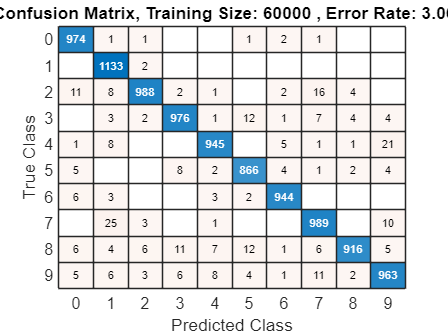

figure;
confusionchart(conf_matrix_knn, class_labels);
title(['Confusion Matrix, Training Size: ',num2str(size(trainv,1)),' , Error Rate: ', num2str(round(error_rate_knn * 100,2)), '%']);